clear
clc

syms Theta_1(t) Theta_2(t) Theta_3(t) R_1(t) t
syms r_1 r_1y r_2 r_3
syms theta_1 theta_2 theta_3 
syms V_r omega_1 omega_2 omega_3 
syms a_r alpha_1 alpha_2 alpha_3

Vr_2=0.75

Vr_2 = 0.7500

Vr_3=1.70

Vr_3 = 1.7000

Vr_1y=0.45

Vr_1y = 0.4500


Fc=sin(Theta_1)*R_1-r_1y;
fc=subs(Fc,[Theta_1, R_1],[theta_1, r_1]);

Fx=-R_1*cos(Theta_1)+r_2*cos(Theta_2)+r_3*cos(Theta_3);
Fx=simplify(Fx,'Steps',5);
fx=formula(subs(Fx,[Theta_1, Theta_2, Theta_3, R_1],[theta_1, theta_2, theta_3, r_1]));

Fy=R_1*sin(Theta_1)-r_2*sin(Theta_2)-r_3*sin(Theta_3);
Fy=simplify(Fy,'Steps',5);
fy=formula(subs(Fy,[Theta_1, Theta_2, Theta_3, R_1],[theta_1, theta_2, theta_3, r_1]));

DFcDt=diff(Fc);
DFxDt=diff(Fx);
DFyDt=diff(Fy);
F1=formula(subs(DFxDt,[diff(R_1),diff(Theta_1),diff(Theta_2),diff(Theta_3),Theta_1,Theta_2,Theta_3,R_1],[V_r,omega_1,omega_2,omega_3,theta_1,theta_2,theta_3,r_1]));
F2=formula(subs(DFyDt,[diff(R_1),diff(Theta_1),diff(Theta_2),diff(Theta_3),Theta_1,Theta_2,Theta_3,R_1],[V_r,omega_1,omega_2,omega_3,theta_1,theta_2,theta_3,r_1]));
F3=formula(subs(DFcDt,[diff(R_1),diff(Theta_1),diff(Theta_2),diff(Theta_3),Theta_1,Theta_2,Theta_3,R_1],[V_r,omega_1,omega_2,omega_3,theta_1,theta_2,theta_3,r_1]));

D2FcDt2=diff(DFcDt);
D2FxDt2=diff(DFxDt);
D2FyDt2=diff(DFyDt);
F4=formula(subs(D2FcDt2,[diff(diff(R_1)),diff(diff(Theta_1)),diff(diff(Theta_2)),diff(diff(Theta_3)),diff(R_1),diff(Theta_1),diff(Theta_2),diff(Theta_3),Theta_1,Theta_2,Theta_3,R_1],[a_r,alpha_1,alpha_2,alpha_3,V_r,omega_1,omega_2,omega_3,theta_1,theta_2,theta_3,r_1]));
F5=formula(subs(D2FxDt2,[diff(diff(R_1)),diff(diff(Theta_1)),diff(diff(Theta_2)),diff(diff(Theta_3)),diff(R_1),diff(Theta_1),diff(Theta_2),diff(Theta_3),Theta_1,Theta_2,Theta_3,R_1],[a_r,alpha_1,alpha_2,alpha_3,V_r,omega_1,omega_2,omega_3,theta_1,theta_2,theta_3,r_1]));
F6=formula(subs(D2FyDt2,[diff(diff(R_1)),diff(diff(Theta_1)),diff(diff(Theta_2)),diff(diff(Theta_3)),diff(R_1),diff(Theta_1),diff(Theta_2),diff(Theta_3),Theta_1,Theta_2,Theta_3,R_1],[a_r,alpha_1,alpha_2,alpha_3,V_r,omega_1,omega_2,omega_3,theta_1,theta_2,theta_3,r_1]));

f(r_1,theta_1,theta_3,V_r,omega_1,omega_3,a_r,alpha_1,alpha_3)=[fc;fx;fy;F1;F2;F3;F4;F5;F6];
f=subs(f,[r_1y,r_2,r_3],[Vr_1y,Vr_2,Vr_3]);
f=simplify(f,'Steps',5);
JacInv=jacobian(f, [r_1,theta_1,theta_3,V_r,omega_1,omega_3,a_r,alpha_1,alpha_3])^-1;


Tabla_Cinematica=readtable("Perfil_cinematica.txt","Delimiter"," ");

p1=[2.4314,0.1862,0.2679,0,0,0,0,0,0]

p1 =     2.4314    0.1862    0.2679         0         0         0         0         0         0


    tic
for i=1:length(Tabla_Cinematica.Tiempo) 
    p1=NR_Sistema(f,JacInv,p1,Tabla_Cinematica.Posicion(i),Tabla_Cinematica.Velocidad(i),Tabla_Cinematica.Aceleracion(i));
    ValoresSolucion(i,:)=p1;
end
    toc

Elapsed time is 93.156772 seconds.


Tabla_Cinematica.R_1=ValoresSolucion(:,1);
Tabla_Cinematica.theta_1=ValoresSolucion(:,2);
Tabla_Cinematica.theta_3=ValoresSolucion(:,3);
Tabla_Cinematica.V_1=ValoresSolucion(:,4);
Tabla_Cinematica.omega_1=ValoresSolucion(:,5);
Tabla_Cinematica.omega_3=ValoresSolucion(:,6);
Tabla_Cinematica.a_1=ValoresSolucion(:,7);
Tabla_Cinematica.alpha_1=ValoresSolucion(:,8);
Tabla_Cinematica.alpha_3=ValoresSolucion(:,9);
Tabla_Cinematica

Tabla_Cinematica = 200×13 table
     Tiempo      Aceleracion    Velocidad     Posicion      R_1      theta_1    theta_3       V_1         omega_1       omega_3        a_1       alpha_1     alpha_3 
    _________    ___________    _________    __________    ______    _______    _______    _________    ___________    __________    _______    _________    ________

            0           0               0             0    2.4314    0.18615     0.2679            0              0             0          0            0           0
    0.0061708      1.5075  

writetable(Tabla_Cinematica,'Resultados.txt','delimiter',' ', 'WriteVariableNames', true)

r_1,theta_1,theta_3,V_r,omega_1,omega_3,a_r,alpha_1,alpha_3

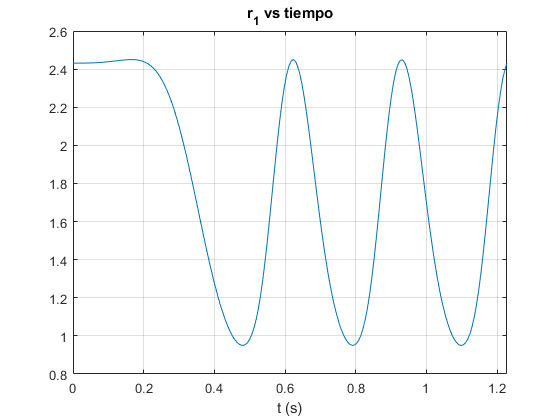

tiempo=Tabla_Cinematica.Tiempo;
figure()
plot(tiempo,Tabla_Cinematica.R_1)
title("r_1 vs tiempo")
xlabel("t (s)")
grid on
xlim([0 tiempo(end)])

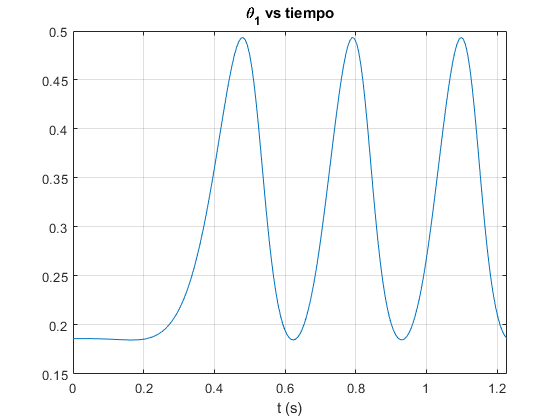


figure()
plot(tiempo,Tabla_Cinematica.theta_1)
title("\theta_1 vs tiempo")
xlabel("t (s)")
grid on
xlim([0 tiempo(end)])

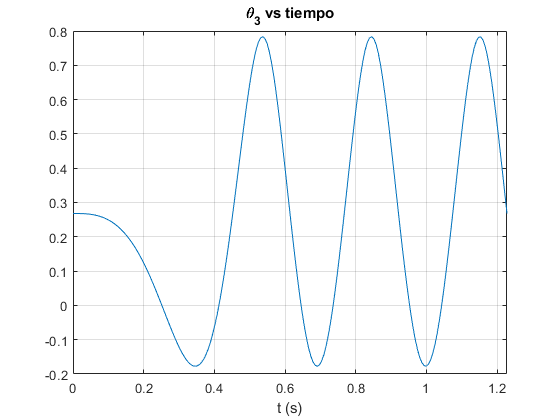


figure()
plot(tiempo,Tabla_Cinematica.theta_3)
title("\theta_3 vs tiempo")
xlabel("t (s)")
grid on
xlim([0 tiempo(end)])

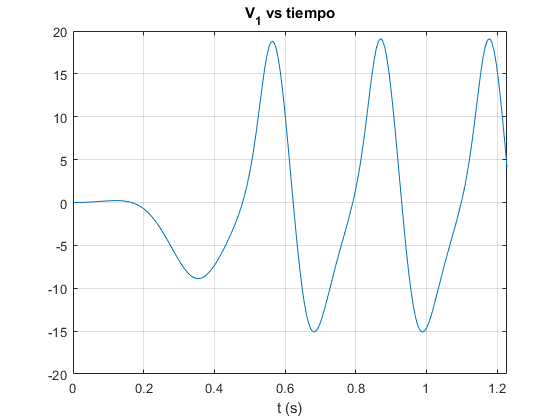


figure()
plot(tiempo,Tabla_Cinematica.V_1)
title("V_1 vs tiempo")
xlabel("t (s)")
grid on
xlim([0 tiempo(end)])

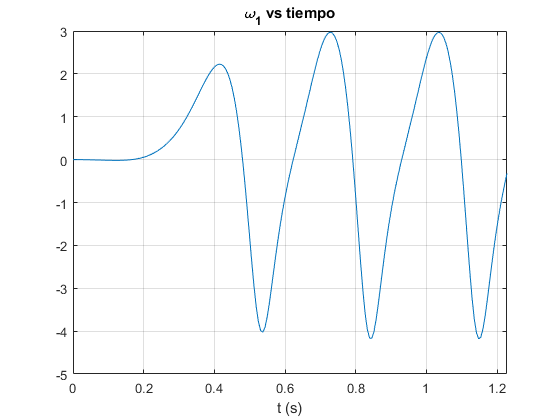


figure()
plot(tiempo,Tabla_Cinematica.omega_1)
title("\omega_1 vs tiempo")
xlabel("t (s)")
grid on
xlim([0 tiempo(end)])

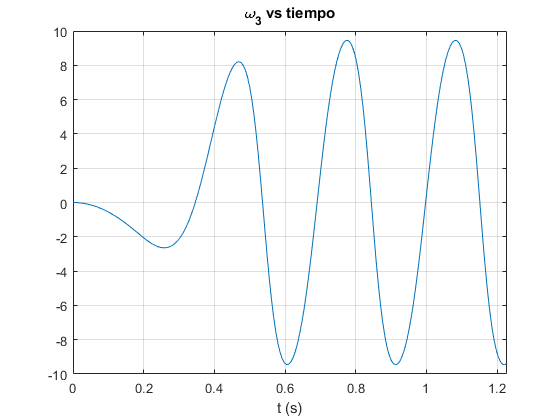


figure()
plot(tiempo,Tabla_Cinematica.omega_3)
title("\omega_3 vs tiempo")
xlabel("t (s)")
grid on
xlim([0 tiempo(end)])

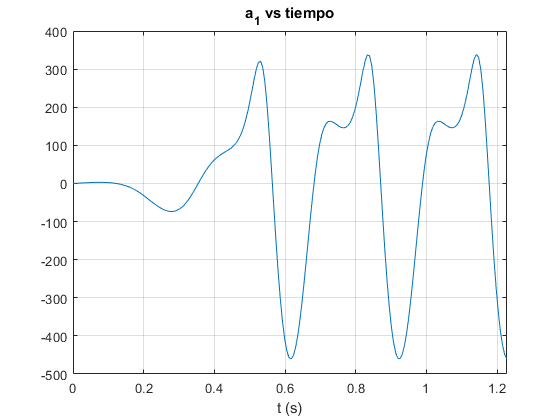


figure()
plot(tiempo,Tabla_Cinematica.a_1)
title("a_1 vs tiempo")
xlabel("t (s)")
grid on
xlim([0 tiempo(end)])

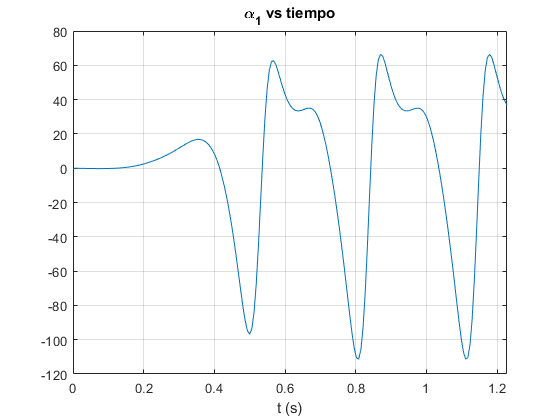


figure()
plot(tiempo,Tabla_Cinematica.alpha_1)
title("\alpha_1 vs tiempo")
xlabel("t (s)")
grid on
xlim([0 tiempo(end)])

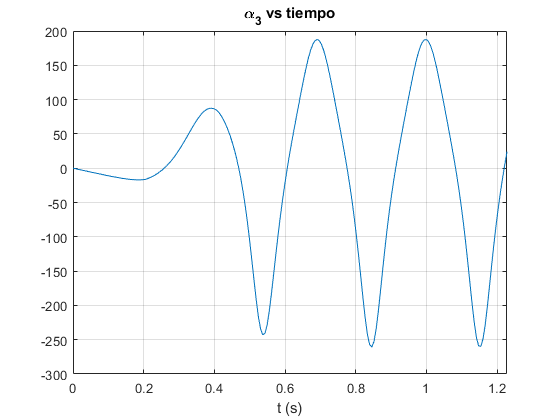


figure()
plot(tiempo,Tabla_Cinematica.alpha_3)
title("\alpha_3 vs tiempo")
xlabel("t (s)")
grid on
xlim([0 tiempo(end)])

function Sol = NR_Sistema(F,FJacInv,Pi,Ftheta_2,Fomega_2,Falpha_2)
syms omega_2 theta_2 alpha_2 
f=subs(F,[theta_2,omega_2,alpha_2],[Ftheta_2,Fomega_2,Falpha_2]);
JacInv=subs(FJacInv,[theta_2,omega_2,alpha_2],[Ftheta_2,Fomega_2,Falpha_2]);
p=Pi';
ValoresNR(1,:)=p';
iteraciones=50;
for i=1:iteraciones
    p=double(p-JacInv(p(1),p(2),p(3),p(4),p(5),p(6),p(7),p(8),p(9))*f(p(1),p(2),p(3),p(4),p(5),p(6),p(7),p(8),p(9)));
    ValoresNR(i+1,:)=double(p)';
    ErrorNR(i,:)=abs(ValoresNR(i,:)-ValoresNR(i+1,:));
    NormErrorNR(i)=norm(ErrorNR(i,:));
     if NormErrorNR(i)<0.0005
        break;
    end
end
    Sol=p';
end